# Benchmarking Forecasting Methodologies

The existing comparisons during COVID-19 are those of forecasts (forecasting teams) rather than forecasting methodologies. Instead of "who did well", we are interested in "what worked well" over the duration of the pandemic

The goal of this work is to compare various methodologies and create a benchmark against which new methodologies can be evaluated. When designing a new methodology, bringing the entire evaluation to one error number is not enough. One has to assess the performance over time, and the difficulty of forecasting is likely to be different over the period. The benchmark, as the performances of collection of methodologies over time, can guide in a better assessment.

This work will also identify various decisions that affect the accuracy of forecasts from the submit methodologies. These "decisions" may include:

- Modeling technique: Generative (SIR, SEIR, ...), Discriminative (Neural Networks, ARIMA, ...), ...

- Learning approach: Bayesian, Regression (Quadratic Programming, Gradient Descent, ...), ...

- Pre-processing: Smoothing (1 week, 2, week, auto), anomaly detection, ...

## Data for evaluation

We use the latest JHU data as the ground truth. Note that this in not to be used for training. 

Forecasts on a past date must use the data that was available that day for training. The versions of JHU data available on various days of the past are available as timeseries in: [https://github.com/scc-usc/ReCOVER-COVID-19/blob/master/results/historical_forecasts](https://github.com/scc-usc/ReCOVER-COVID-19/blob/master/results/historical_forecasts)

clc, clear all, close all
warning off;
addpath('./hyper_params/');
load_data_us;

## List of methods already included

- LANL_GrowthRate: https://covid-19.bsvgateway.org/

- YYG-ParamSearch: [https://github.com/youyanggu/covid19_projections](https://github.com/youyanggu/covid19_projections)

- CU _SELECT: [https://github.com/shaman-lab/COVID-19Projection](https://github.com/shaman-lab/COVID-19Projection)

- **[Our Approach] SIkJ**$\alpha$ : [https://github.com/scc-usc/ReCOVER-COVID-19](https://github.com/scc-usc/ReCOVER-COVID-19)

The current files are derived from: [https://github.com/reichlab/covid19-forecast-hub/tree/master/data-processed](https://github.com/reichlab/covid19-forecast-hub/tree/master/data-processed)

Only those were selected that produce forecasts on more than one day a week.

As described earlier, we would like to switch to methodologies. We invite the interested teams to submit forecasts generated by their methodology using the historical versions of JHU data at: [https://github.com/scc-usc/ReCOVER-COVID-19/blob/master/results/historical_forecasts](https://github.com/scc-usc/ReCOVER-COVID-19/blob/master/results/historical_forecasts)

Please note that any change in your approach, including data pre-processing and hand-tuning a parameter counts as a different methodology. The instructions for submitting your forecasts to us are available at: [https://github.com/scc-usc/covid19-forecast-bench](https://github.com/scc-usc/covid19-forecast-bench)


lastday = size(deaths, 2)-1; 
firstday = 120;
skipdays = 7;

time_stamps =(firstday:lastday);

data_src = {'JHU'}; % Next we list methods that use these data sources in order
method_list{1} = {'LANL_GrowthRate'; 'YYG_ParamSearch'; 'CU_select'; 'SIkJa_USC'};

% Loading other forecasts
for ml_idx = 1:length(method_list)
    methods = method_list{ml_idx};
    for mm = 1:length(methods)
        for tt = 1:length(time_stamps)
            try
                fname = [methods{mm}, '_', num2str(time_stamps(tt)+1), '.csv'];
                preds = readtable(['../results/others_death_forecasts/biweekly_reports/', fname]);
                preds = preds{1:end, 3:end};
                preds(1, 1) = preds(1, 1) - 1; % Correcting the discrepancy in date labeling
                eval([methods{mm}, '{',  num2str(tt),'} = ', 'preds;']);
            catch
                eval([methods{mm}, '{',  num2str(tt),'} = ', '-1;']);
            end
        end
        disp(['Loaded for ', methods{mm}]);
    end
end

Loaded for LANL_GrowthRate
Loaded for YYG_ParamSearch
Loaded for CU_select
Loaded for SIkJa_USC


## Forecasts from our methodology (one version)

Forecasts generated by the current verison of our methodology are available in [https://github.com/scc-usc/ReCOVER-COVID-19/blob/master/results/historical_forecasts](https://github.com/scc-usc/ReCOVER-COVID-19/blob/master/results/historical_forecasts)

In the future, more versions will be added to be compared as separate methodologies. Note that, any change, including simply changing the smoothing factor is also considered to be a different methodology. 

% Our results are generated in daily format. 
% So we convert them to the common format for evaluation as described before.

a_sunday = 94; % We will use this to identify which other columns should be Sundays
for tt = 1:length(time_stamps)-1 % Pick some days and generate forecasts
    
    forecast_date = datetime(2020, 1, 24)+caldays(time_stamps(tt));
    path = '../results/historical_forecasts/';
    dirname = datestr(forecast_date, 'yyyy-mm-dd');
    fullpath = [path dirname];
    
    dtab = readtable([fullpath '/' prefix '_forecasts_deaths.csv']);
    death_pred = dtab{2:end, 4:end};
    base_deaths1 = dtab{2:end, 3};  % deaths observed in the day of forecasts
    dcols = time_stamps(tt)+1:(time_stamps(tt)+(size(death_pred, 2)));
    try
        dow = mod(tt-a_sunday, 7) + 1;
        if  dow == 1 || dow == 2 %If the sunday before has been observed, use the observed as base deaths
            base_deaths = deaths(:, time_stamps(tt) - dow + 1);
            first_pred_sunday = time_stamps(tt) - dow + 1+ 7;
        else
            base_idx = find(dcols == (time_stamps(tt)+8-dow));
            base_deaths = death_pred(:, base_idx(1));
            first_pred_sunday = time_stamps(tt) + 8 - dow + 7;
        end
    catch
        continue;
    end
    
    first_sunday_idx = find(dcols==first_pred_sunday);
    sun_cols = dcols(first_sunday_idx(1):7:end);
    
    weekly_preds = [base_deaths1, diff([base_deaths death_pred(:, first_sunday_idx(1):7:end)]')'];
    SIkJa_USC{tt} = [[time_stamps(tt) sun_cols]; weekly_preds];
    fprintf('.');
end

.....................................................................................................................

## Error matrices

We generate a matrix where element (i, j) represents the error of forecast generated on day i for week j. The forecasts are expected to be incident cases forecasts per week. We do not compute the errors for a week when the forecast was performed on a day after Monday of the same week. This is in accordance with the forecasting hub.

first_tt = 1;
cidx = popu > -1;
cidx([51, 52, 53, 55, 56]) = 0; % Others do not forecast for these states
all_sundays = (firstday+7-mod(firstday-a_sunday, 7)):7:size(deaths, 2); % All sundays in the data
sun_map = containers.Map(all_sundays, 1:length(all_sundays));

sunday_gt  = [(a_sunday+7:7:size(deaths, 2));diff(deaths(:, a_sunday:7:end)')'];
for mm = 1:length(methods)
    err_mat = nan(lastday-firstday+1, length(all_sundays));
    err_mat1 = err_mat;
    for tt=first_tt:length(time_stamps)
        pred_files = eval([methods{mm} '{' num2str(tt) '}']);
        
        if length(pred_files) == 1
            continue;
        end
        rem_idx = pred_files(1, :) > size(deaths, 2); % If the data has not been observed, remove the prediction
        pred_files(:, rem_idx) = [];
        pred_dates = pred_files(1, 2:end);
        
        if length(pred_dates) < 1 % This means only the base deaths are left, no forecast to evaluate
            continue;
        end
        
        if any(diff(pred_dates) ~= 7) && length(pred_dates)>1
            continue;
        end
        
        gt_start = find(sunday_gt(1, :) == pred_dates(1)); % sundays on or after predicted days

        gt = sunday_gt(logical([0; cidx]), int32(gt_start(1):1:gt_start(1)+length(pred_dates)-1));
        preds = pred_files(2:end, 2:end);
        preds = (preds(cidx, :) + abs(preds(cidx, :)))/2;
        err_vec = nanmean(2*abs(gt-preds)./abs(gt+preds), 1);
        err_vec1 = nanmean(abs(gt-preds), 1);
        if any(isinf(err_vec))
            fprintf('.');
        end
        
        mapped_vec = arrayfun(@(x)sun_map(x), pred_dates);
        err_mat(tt, mapped_vec) = err_vec;
        err_mat1(tt, mapped_vec) = err_vec1;
    end
    eval(['SMAPE_' methods{mm}  '= err_mat;']);
    eval(['MAE_' methods{mm}  '= err_mat1;']);
end


## Heatmap

Visualizing the errors: the vertical axis is a day id representing the day of generating the forecasts, and the horizontal axes is an id representing the target week.

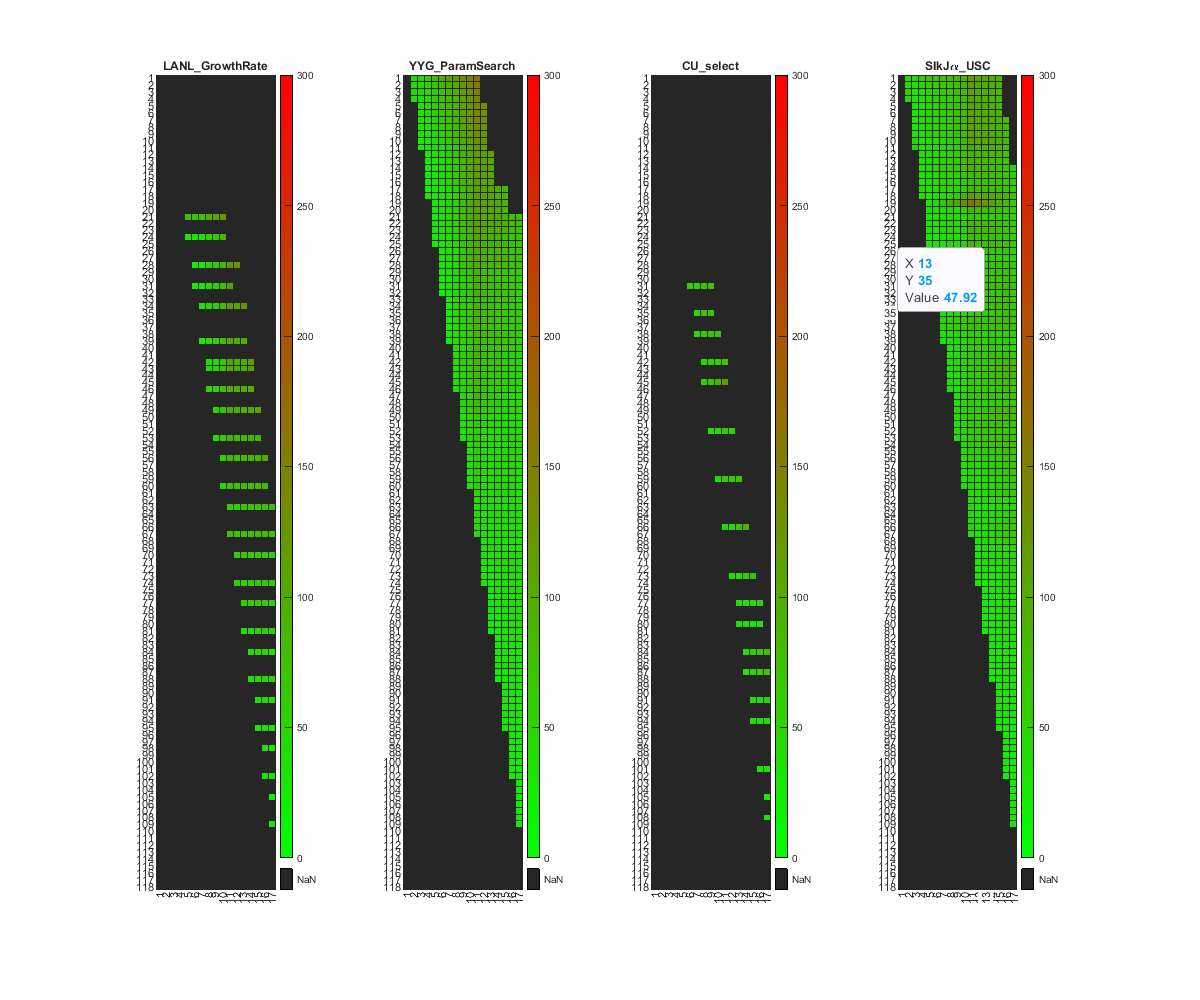

figure('DefaultAxesFontSize',14);
%figure;
set(gcf,'position',[10,10,1200,1000]);
climit = 300;
ll = strrep(methods, '_', '\_');
ll = strrep(ll, 'SIkJa', 'SIkJ\alpha');
     
mymap = [(0:1:climit)' (climit:-1:0)' zeros(climit+1, 1)]./climit;
for mm=1:length(methods)
    subplot(1, length(methods), mm);
    heatmap(eval(['MAE_' methods{mm}]), 'Colormap', mymap, 'ColorLimits',[0 300]);
    title(ll{mm});
end

## x-week-ahead forecast errors

On a given date, 1-week-ahead is the incident forecast for the week ending on that week if the forecast is performed on a Sunday or a Monday, and the next week if the forecast is performed on other days of the week. This is in accordance with Reich Lab forecast submissions. Same rule is used for 2-, 3-, 4-week ahead calculations

for mm=1:length(methods)
    err_mat1 = eval(['MAE_' methods{mm}]);
    tot_ahead = 4;
    ahead_error = nan(tot_ahead, size(err_mat1, 1));
    for aidx = 1:tot_ahead
        for tt=first_tt:length(time_stamps)
            sun_lb = time_stamps(tt) + aidx*7 - 1;
            sun_ub = time_stamps(tt) + aidx*7 + 5;
            sun_idx = find(all_sundays >= sun_lb & all_sundays <= sun_ub);
            
            if ~isempty(sun_idx)
               ahead_error(aidx, tt) = err_mat1(tt, sun_idx(1)); 
            end
        end
    end
    eval(['ahead_error_' methods{mm} ' = ahead_error;']);
end


## 1-, 2-, 3-, 4-week-ahead plots

Errors for x-week ahead for a forecast made from data available on the "date of release".

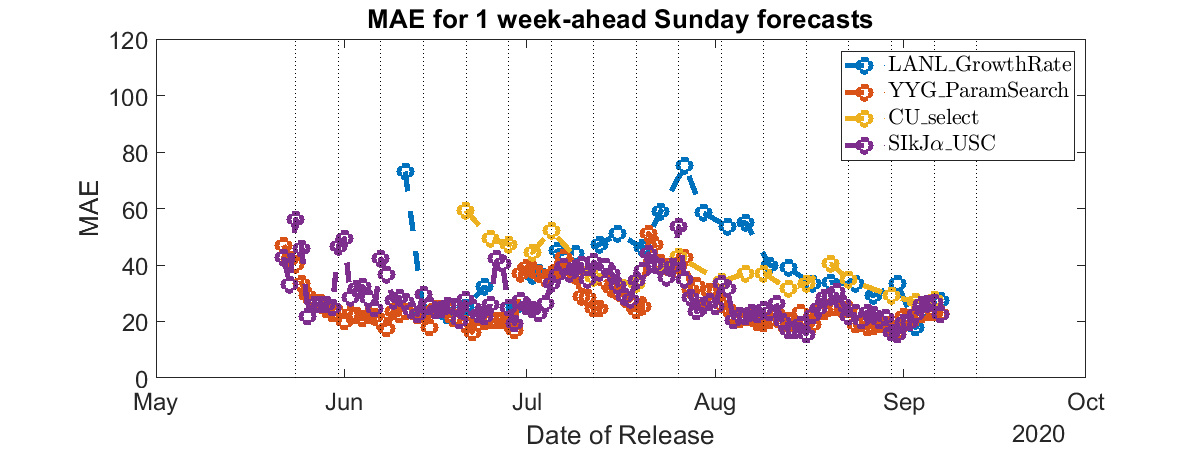

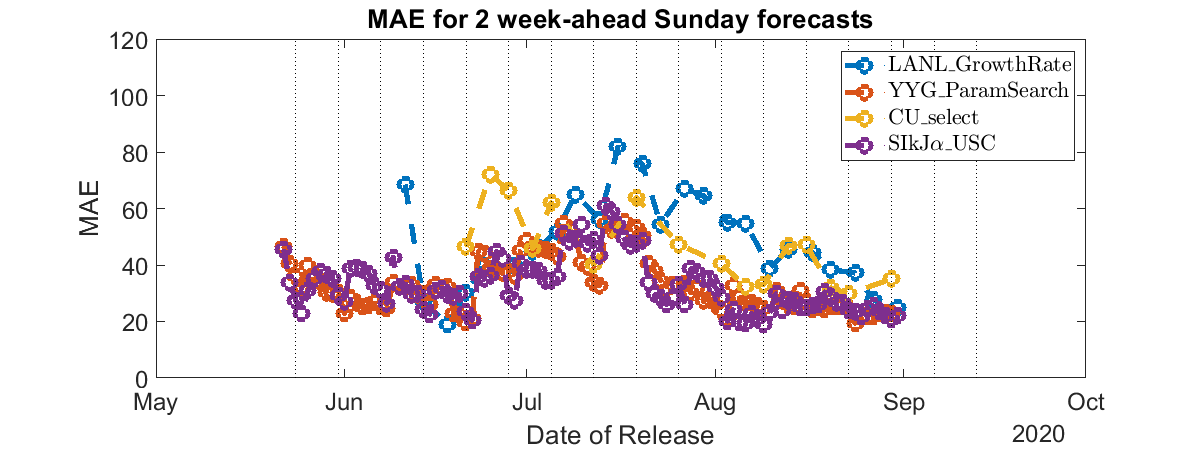

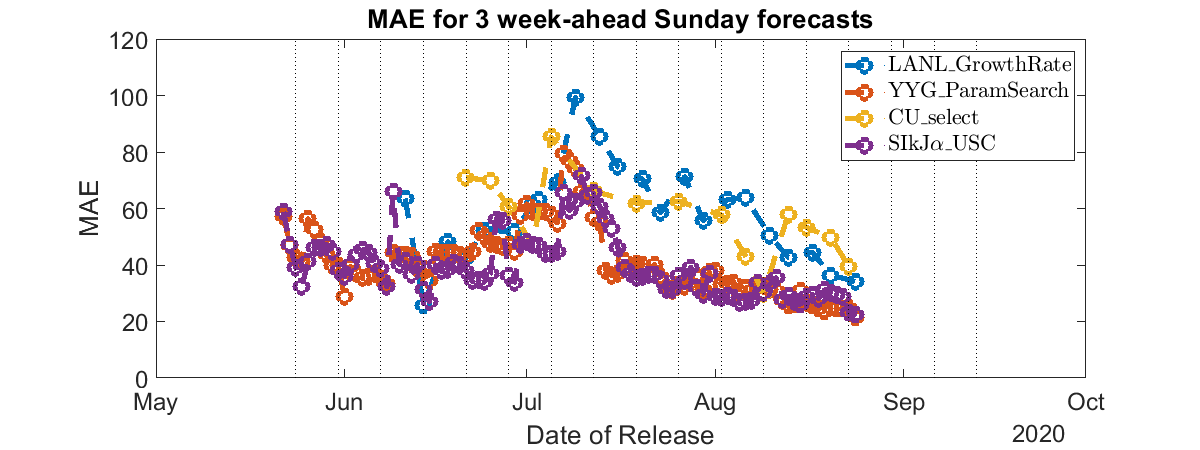

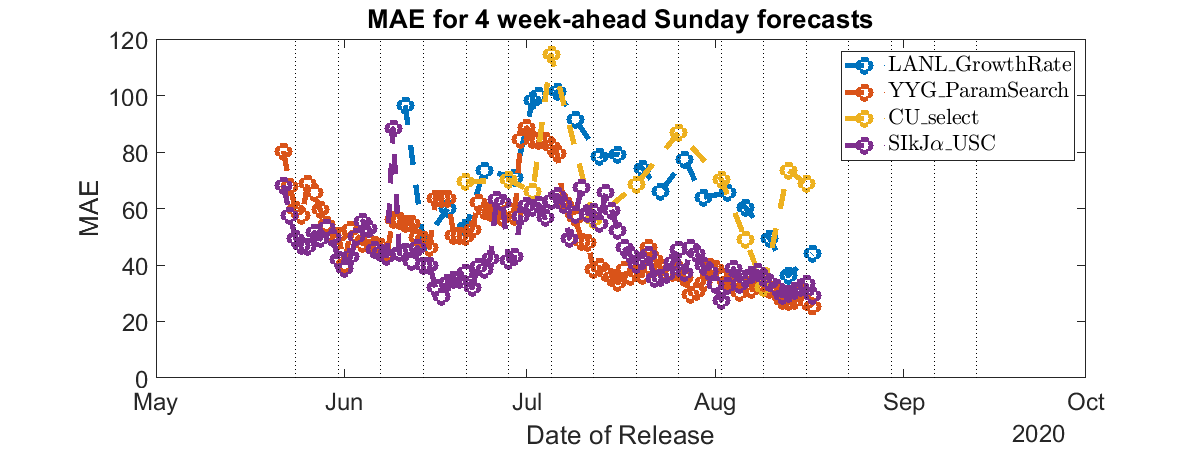

for aidx = 1:4
    figure('DefaultAxesFontSize',18);
    set(gcf,'position',[10,10,1200,450]);
    for mm=1:length(methods)
        eval(['ahead_error = ahead_error_' methods{mm} ';']);
        errs = ahead_error(aidx, :);
        nnanidx = ~isnan(errs);
        Tx = datetime(2020, 1, 23)+ caldays(time_stamps);
        plot(Tx(nnanidx), errs(nnanidx), 'Marker', 'o', 'LineStyle',"--", 'LineWidth', 4, 'MarkerSize', 10); hold on;
    end
    title(['MAE for ' num2str(aidx) ' week-ahead Sunday forecasts']);
    xlabel('Date of Release');
    ylabel('MAE');
    ylim([0, Inf]);
    
    g_x = datetime(2020, 1, 23)+ caldays(all_sundays);
    %xticks(sundates);
    for i=1:length(g_x)
        plot([g_x(i) g_x(i)],[0 120],'k:') %x grid lines
        hold on
    end
    hold off;
    ll = strrep(methods, '_', '\_');
    ll = strrep(ll, 'SIkJa', 'SIkJ$\alpha$');
    %legend(ll, "Interpreter","latex", 'location', 'eastoutside');
    legend(ll, "Interpreter","latex");
end

## 1, 2, 3, and 4-week-ahead day-wise

How do the errors vary depending on the day of the week when the forecasts were generated?

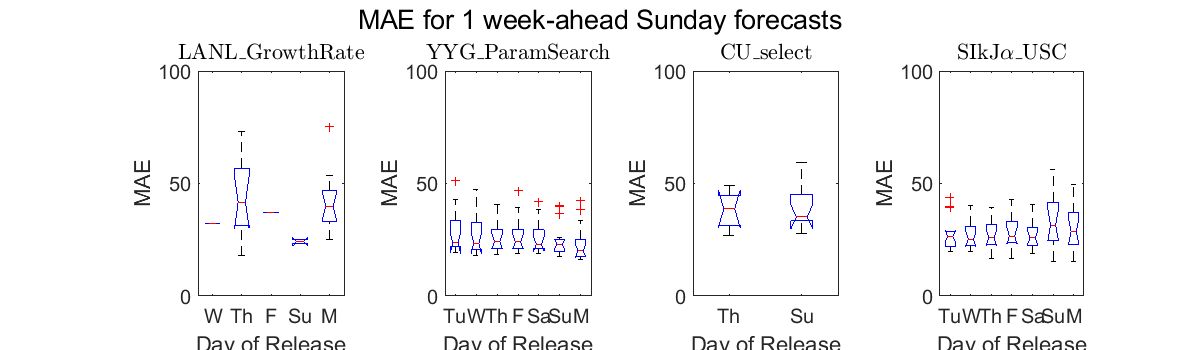

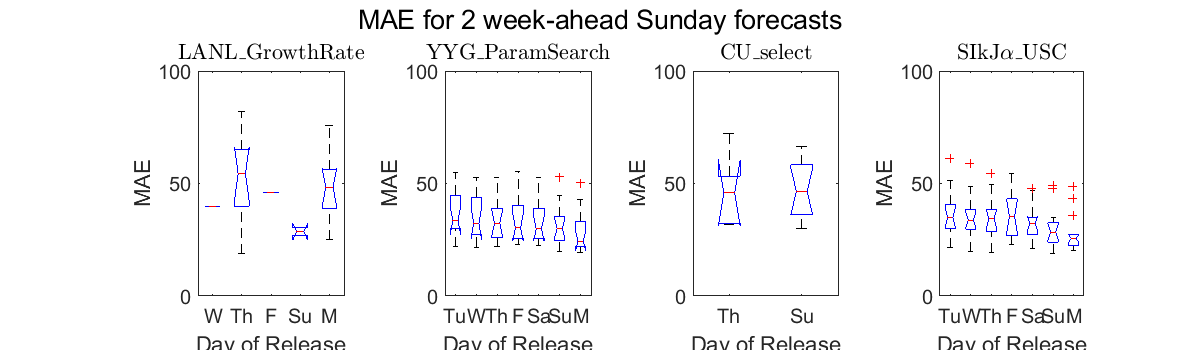

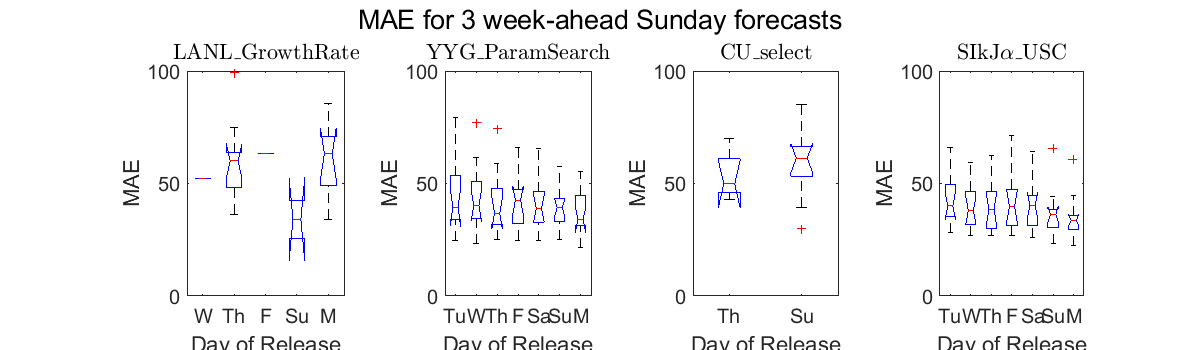

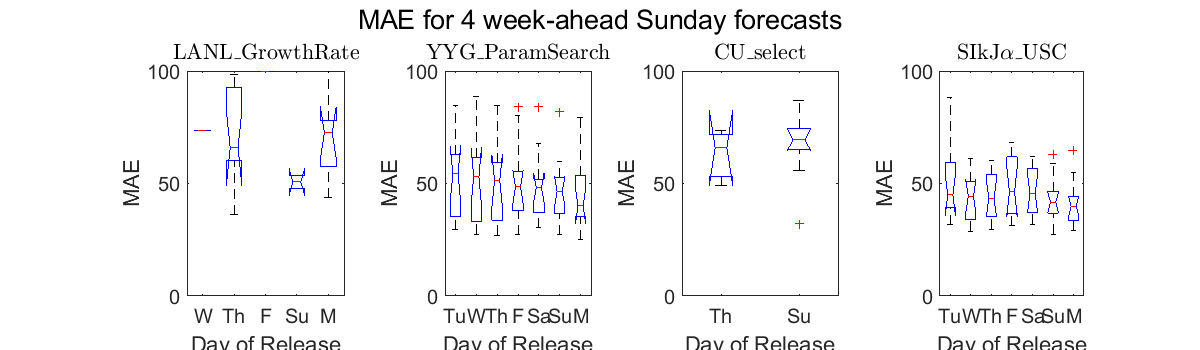

daylabels = {'Su', 'M', 'Tu', 'W', 'Th', 'F', 'Sa'};
dayorder = {'Tu', 'W', 'Th', 'F', 'Sa', 'Su', 'M'};
for aidx = 1:4
    figure('DefaultAxesFontSize',16);
    set(gcf,'position',[10,10,1200,350]);
    for mm=1:length(methods)
        eval(['ahead_error = ahead_error_' methods{mm} ';']);
        errs = ahead_error(aidx, :);
        nnanidx = ~isnan(errs);
        
        day_idx = mod(time_stamps-a_sunday, 7)+1; 
        subplot(1, 4, mm); 
        %scatter(day_idx(nnanidx), errs(nnanidx), 10);
        
        xx = unique(daylabels(day_idx(nnanidx)));
        keepidx = zeros(7, 1);
        for ii=1:length(dayorder)
            if any(strcmpi(dayorder(ii), xx)==1)
                keepidx(ii) = 1;
            end
        end
        thisorder = dayorder(keepidx>0);
        boxplot(errs(nnanidx), daylabels(day_idx(nnanidx)), 'GroupOrder',thisorder, 'Notch',"on");
        ylim([0, 100]);
        xlabel('Day of Release');
        ylabel('MAE');
        title(ll{mm}, "Interpreter","latex");
    end
    suptitle(['MAE for ' num2str(aidx) ' week-ahead Sunday forecasts']);
    hold off;
%     title(['MAE for ' num2str(aidx) ' week-ahead Sunday forecasts']);
%     xlabel('Day of Release');
%     ylabel('MAE');
%     ylim([0, Inf]);
%     ll = strrep(methods, '_', '\_');
%     ll = strrep(ll, 'SIkJa', 'SIkJ$\alpha$');
%     %legend(ll, "Interpreter","latex", 'location', 'eastoutside');
%     legend(ll, "Interpreter","latex");
end